## Results

    Now that we have the explicit function for the position of the ball's future bounces, given a set of its initial conditions and surface orientation, we can then use established numerical optimization methods to control the ball's bounces such that it lands at a desired target position, if possible. We can then test this controller against our previously developed numerical simulation by calculating the ideal surface orientation while the simulation is running, as if the controller were running in real time on a physical system.

    To demonstrate this controller, we can first test for cases where the table only needs to be adjusted once, such that the trajectory exiting the first bounce will end with the ball at the target position. We choose these cases first because they are the easiest to represent in a single static image, as one does not need to consider displaying the movement of the surface, and the associated changes in the bounce Z positions.

    Using the initial position $\vec{P(0)} = \left[
\matrix{
10 \cr
10 \cr
15
}
\right]$and initial velocity $\vec{V(0)} = \left[
\matrix{
2 \cr
-2 \cr
2
}
\right]$, we arrive at the following simulation resuls:

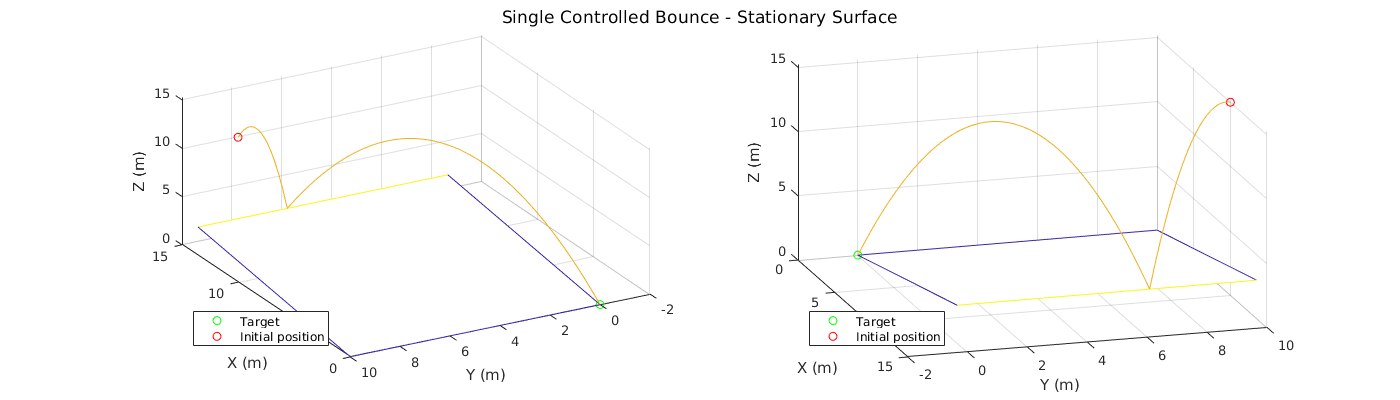

nBounces = 2;
timeout = 10; % seconds
coeff_restitution = 0.95; % unitless
g = 9.80; % m/s^2

p_0 = [10; 10; 15];
v_0 = [2; -2; 2];
origin = [0; 0; 0];

[T, States, Normals, ~, bounceTimes] = bounceSim(nBounces, timeout, [p_0, v_0], g, coeff_restitution, origin, @calculate_normal, [0, 0], false);

figure();
set(gcf, 'position', [0 0 1400 400])
sgtitle("Single Controlled Bounce - Stationary Surface")

subplot(1, 2, 1)
plot_bounce(States, p_0, Normals(1, :), T, bounceTimes);
view(240.7, 41.2)
legend('Target', 'Initial position', 'Location',"southwest")

subplot(1, 2, 2)
plot_bounce(States, p_0, Normals(1, :), T, bounceTimes);
view(73, 27.4)
legend('Target', 'Initial position', 'Location',"southwest")

    As expected, the calculated optimal surface orientation correctly aim's the ball's second bounce to the target position (the origin, $(0, 0, 0)$), only using a single bounce to do so. This raises the question: Even if the controller can get the ball to the center, can it *keep* the ball at the center? Since the ball is approaching with a certain amount of X and Y velocity, can we truly negate this, preventing the ball from just bouncing past the center? To test this we set up a scenario where given the set of initial conditions the first bounce of the ball would land directly at the target position. Thus, we can see if the controller-generated surface orientations are able to negate the horizontal velocity components and keep the ball at the center. 

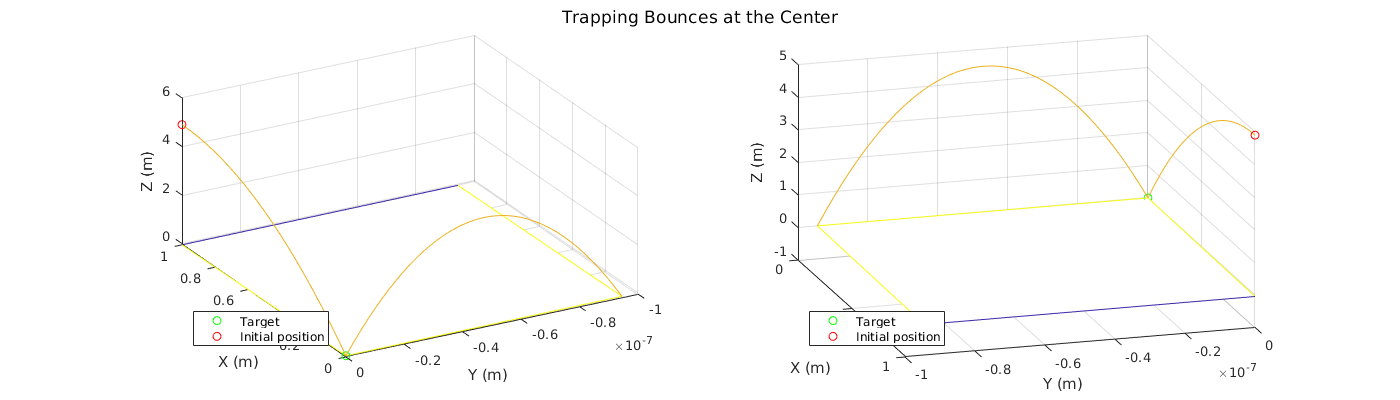

v_0 = [-1; 0; 0];
p_0 = [1; 0; -(1^2 * g) / (2 * v_0(1))];

[T, States, Normals, ~, bounceTimes] = bounceSim(nBounces, timeout, [p_0, v_0], g, coeff_restitution, origin, @calculate_normal, [0, 0], false);

figure();
set(gcf, 'position', [0 0 1400 400])
sgtitle("Trapping Bounces at Target Position")

subplot(1, 2, 1)
plot_bounce(States, p_0, Normals(1, :), T, bounceTimes);
view(240.7, 41.2)
legend('Target', 'Initial position', 'Location',"southwest")

subplot(1, 2, 2)
plot_bounce(States, p_0, Normals(1, :), T, bounceTimes);
view(73, 27.4)
legend('Target', 'Initial position', 'Location',"southwest")

    While at first it may seem as if the controller is unable to keep the ball at the center, the scale of the Y axis ($10^{-7}$) reveals that in fact, the controller is actually able to keep the ball in the center. Thus, we have established that 1) The controller is able to direct balls to land at the center, if possible, and 2) Once a ball lands at the center, the controller is able to keep it there.

    This leaves us with one last problem. So far, all simulations of the bouncing ball system have been with a single bounce. However, to truly simulate the system realistically, and to account for cases where the ball physically cannot bounce to the center with just one bounce, a simulation that allows for control of multiple consecutive bounces is required. We can test such a simulation with a scenario where the ball is unable to bounce to the center in one try. Such a scenario can be set up if, using the same $\vec{V(0)} = \left[
\matrix{
2 \cr
-2 \cr
2
}
\right]$ as in the first example, we instead move the starting position to$\vec{P(0)} = \left[
\matrix{
50 \cr
50 \cr
20
}
\right]$. In this case, for the ball to bounce to the target location, additional bounces, and therefore surface adjustments, will be needed. Unfortunately, there is not good way to plot the surface orientation adjustments in a stationary plot. To approximate this, we instead can plot the surface orientation at the time of each bounce at each bounce location.

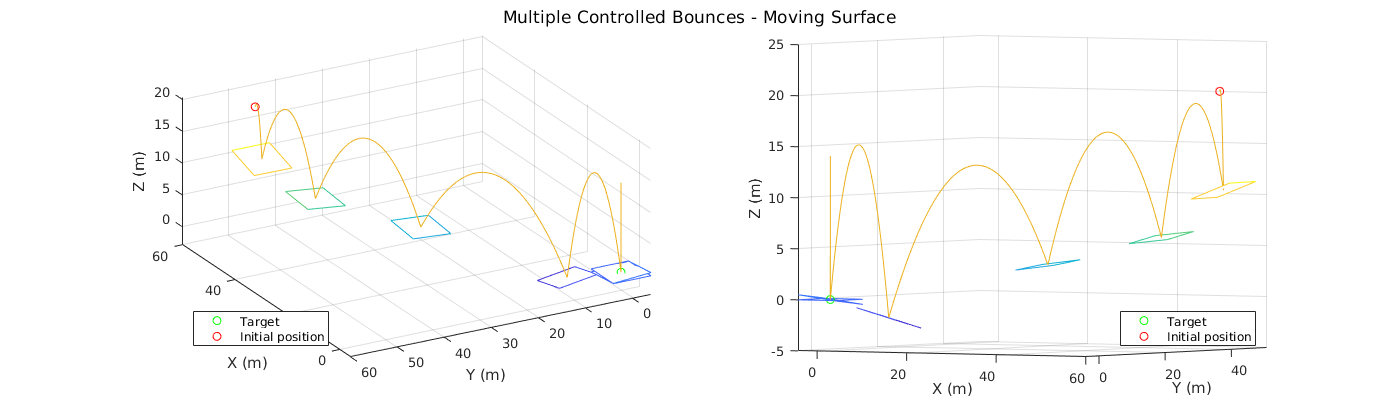

p_0 = [50; 50; 20];
nBounces = 15;

[T, States, Normals, ~, bounceTimes] = bounceSim(nBounces, timeout, [p_0, v_0], g, coeff_restitution, origin, @calculate_normal, [0, 0], true);
figure()
set(gcf, 'position', [0 0 1400 400])
sgtitle("Multiple Controlled Bounces - Moving Surface")

subplot(1, 2, 1)
plot_bounce(States, p_0, Normals, T, bounceTimes);
view(240.7, 41.2)

subplot(1, 2, 2)
plot_bounce(States, p_0, Normals, T, bounceTimes);
view(32.2179, 2.1489)
ax = gca;
ax.Legend.Location = 'southeast';

Notice that there are 6 distinct planes that are visible in these plots. However, this simulation was set up such that the ball will bounce 15 times. The remaining 9 planes are missing because they are all overlapping each other at the target position, as since the ball has arrived at the target position and has had its horizontal velocity components negated, forming the vertical trajectory at the target position. This becomes even clearer when one plots the distance to the target over time:

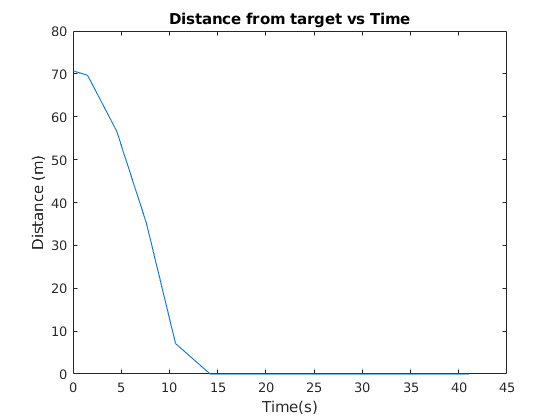

figure()
distances = sqrt(States(:, 1).^2 + States(:, 2).^2);
plot(T, distances);
title("Distance from target vs Time")
xlabel('Time(s)')
ylabel("Distance (m)")

This confirms that the ball is able to be kept at the target position by the controlled surface

Now that we can optimize the surface orientation such that the ball can be controlled towards an arbitrary target position, it is a very straightforward extension to allow for the ball to be controlled to moving target positions. Here, we simulate for a set of targets that are moving along the line $y = x$

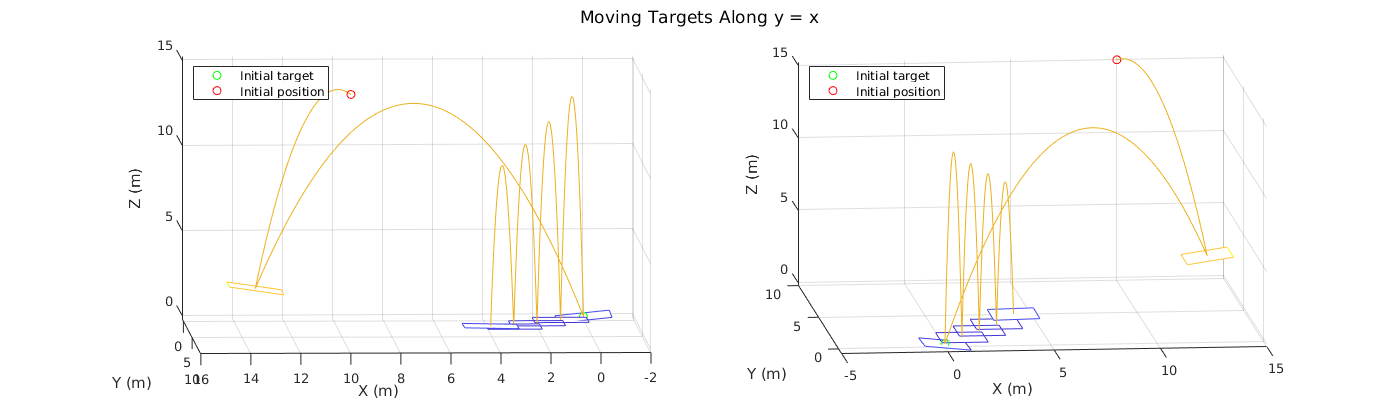

p_0 = [10; 10; 15];
v_0 = [2; -2; 2];

Targets = [0, 0;
            0, 0;
            1, 1;
            2, 2;
            3, 3;
            4, 4;];
target = [0, 0];

nBounces = size(Targets, 1);

[T, States, Normals, Targets, bounceTimes] = bounceSim(nBounces, timeout, [p_0, v_0], g, coeff_restitution, origin, @calculate_normal, Targets, true);

figure()
set(gcf, 'position', [0 0 1400 400])
sgtitle("Moving Targets Along y = x")

subplot(1, 2, 1)
plot_bounce(States, p_0, Normals, T, bounceTimes);
view([177.6 7.6])
ax = gca;
ax.Legend.Location = 'northwest';
ax.Legend.String{1} = 'Initial target';

subplot(1, 2, 2)
plot_bounce(States, p_0, Normals, T, bounceTimes);
view([-5.9 17.1])
ax = gca;
ax.Legend.Location = 'northwest';
ax.Legend.String{1} = 'Initial target';